
%% =========================
% 0) CONFIG / PARAMETERS
% =========================
clear; clc; close all;

symbol        = "MSFT";
startDate     = datetime(2020,1,1);
endDate       = datetime(2023,12,31);

lookbackBB    = 20;     % Bollinger window
numStd        = 2;      % 2-sigma bands
horizon       = 5;      % 5-day forward return target

% Signal thresholds (same idea as your report)
buy_threshold  = 0.01;    % +1%
sell_threshold = -0.005;  % -0.5%

% Backtest settings
initial_capital = 100000;
position_frac   = 0.20;    % 20% of cash per trade
commission      = 0.001;   % 0.1%

% Transformer settings
seqLen        = 30;      % past 30 days of features -> predict horizon return
trainRatio    = 0.70;    % chronological split
rng(42);

%% =========================
% 1) LOAD DATA (CSV)
% =========================
% CSV must have at least: timestamp, adjusted_close
T = readtable("MSFT_daily.csv");  % <-- change filename
T.timestamp = datetime(T.timestamp);
T = sortrows(T, "timestamp");

% filter date range
T = T(T.timestamp >= startDate & T.timestamp <= endDate, :);

prices = T.adjusted_close;
dates  = T.timestamp;


%% =========================
% 2) PREPROCESSING (FIXED)
% =========================

% Ensure numeric type
prices = double(prices(:));
dates  = dates(:);

% Remove missing price values ONLY (not dates)
valid = ~isnan(prices);

prices = prices(valid);
dates  = dates(valid);

% Daily returns
ret1 = [NaN; diff(prices)./prices(1:end-1)];

%% =========================
% 3) FEATURE ENGINEERING
% =========================

% Bollinger bands
ma = movmean(prices, lookbackBB, 'Endpoints','discard');
sd = movstd(prices, lookbackBB,  'Endpoints','discard');

% Align lengths (because mov* with 'discard' shortens)
pad = lookbackBB - 1;
ma = [NaN(pad,1); ma];
sd = [NaN(pad,1); sd];

upper = ma + numStd*sd;
lower = ma - numStd*sd;

% %B and bandwidth
pctB = (prices - lower) ./ (upper - lower);
bandwidth = (upper - lower) ./ ma;

% Distances (normalized)
dist_upper = (upper - prices) ./ ma;
dist_lower = (prices - lower) ./ ma;

% RSI(14)
rsiLen = 14;
chg = [NaN; diff(prices)];
gain = max(chg,0);
loss = max(-chg,0);
avgGain = movmean(gain, rsiLen, 'Endpoints','shrink');
avgLoss = movmean(loss, rsiLen, 'Endpoints','shrink');
RS = avgGain ./ (avgLoss + eps);
RSI = 100 - (100 ./ (1 + RS));

% ROC(10)
rocLen = 10;
ROC = [NaN(rocLen,1); (prices(rocLen+1:end) - prices(1:end-rocLen)) ./ prices(1:end-rocLen)];

% Feature matrix (same spirit as your report)
X = [pctB, bandwidth, RSI, ROC, ret1, dist_upper, dist_lower];

featureNames = ["pctB","bandwidth","RSI","ROC","ret1","dist_upper","dist_lower"];

%% =========================
% 4) TARGET: 5-DAY FORWARD RETURN
% =========================
Y = NaN(size(prices));
Y(1:end-horizon) = (prices(1+horizon:end) - prices(1:end-horizon)) ./ prices(1:end-horizon);

% Remove rows with NaNs in any feature/target
ok = all(~isnan(X),2) & ~isnan(Y);
X = X(ok,:);
Y = Y(ok);
prices2 = prices(ok);
dates2  = dates(ok);
upper2  = upper(ok);
lower2  = lower(ok);
pctB2   = pctB(ok);

%% =========================
% 5) BUILD SEQUENCES (seqLen -> predict Y)
% =========================
numObs = size(X,1);
numFeat = size(X,2);

% sample i uses X(i-seqLen+1 : i, :) to predict Y(i)
startIdx = seqLen;
endIdx   = numObs;

N = endIdx - startIdx + 1;

Xseq = cell(N,1);
Yseq = zeros(N,1);
price_aligned = zeros(N,1);
upper_aligned = zeros(N,1);
lower_aligned = zeros(N,1);
pctB_aligned  = zeros(N,1);
dates_aligned = NaT(N,1);

k = 1;
for i = startIdx:endIdx
    window = X(i-seqLen+1:i, :);           % [seqLen x numFeat]
    Xseq{k} = window.';                    % [numFeat x seqLen] (DL expects features x time)
    Yseq(k) = Y(i);
    
    % keep aligned series for signals/backtest
    price_aligned(k) = prices2(i);
    upper_aligned(k) = upper2(i);
    lower_aligned(k) = lower2(i);
    pctB_aligned(k)  = pctB2(i);
    dates_aligned(k) = dates2(i);
    k = k + 1;
end

%% =========================
% 6) TRAIN/TEST SPLIT + STANDARDIZE (train stats only)
% =========================
N = numel(Xseq);
split = floor(trainRatio * N);

Xtrain = Xseq(1:split);
Ytrain = Yseq(1:split);

Xtest  = Xseq(split+1:end);
Ytest  = Yseq(split+1:end);

% Standardize each feature using training data statistics
% Compute mean/std across ALL time steps of ALL train sequences
allTrain = cat(2, Xtrain{:});  % [numFeat x (seqLen*split)]
mu = mean(allTrain, 2);
sg = std(allTrain, 0, 2) + 1e-8;

XtrainZ = cellfun(@(a) (a - mu)./sg, Xtrain, 'UniformOutput', false);
XtestZ  = cellfun(@(a) (a - mu)./sg, Xtest,  'UniformOutput', false);

%% =========================
% 7) TRANSFORMER MODEL (R2025a)
%    selfAttentionLayer + FFN + Residual (skip) connections
% =========================

dModel   = 64;
numHeads = 4;
ffnDim   = 128;
dropout  = 0.1;

% --- Define layers (with names for graph wiring)
in   = sequenceInputLayer(numFeat, "Name","in", "Normalization","none");

proj = fullyConnectedLayer(dModel, "Name","proj");     % numFeat -> dModel

% Self-attention sub-block
sa   = selfAttentionLayer(numHeads, dModel, ...
        "Name","sa1", ...
        "Dropout", dropout);

dropSA = dropoutLayer(dropout, "Name","dropSA");

add1 = additionLayer(2, "Name","add1");                % residual add
ln1  = layerNormalizationLayer("Name","ln1");

% Feed-forward sub-block
ff1  = fullyConnectedLayer(ffnDim, "Name","ff1");
relu = reluLayer("Name","relu1");
dropFF = dropoutLayer(dropout, "Name","dropFF");
ff2  = fullyConnectedLayer(dModel, "Name","ff2");

add2 = additionLayer(2, "Name","add2");                % residual add
ln2  = layerNormalizationLayer("Name","ln2");

% Pooling + regression head
gap  = globalAveragePooling1dLayer("Name","gap");
fc1  = fullyConnectedLayer(32, "Name","fc1");
relu2 = reluLayer("Name","relu2");
out  = fullyConnectedLayer(1, "Name","out");
reg  = regressionLayer("Name","reg");

% --- Build layer graph
lgraph = layerGraph();
lgraph = addLayers(lgraph, in);
lgraph = addLayers(lgraph, proj);

lgraph = addLayers(lgraph, sa);
lgraph = addLayers(lgraph, dropSA);
lgraph = addLayers(lgraph, add1);
lgraph = addLayers(lgraph, ln1);

lgraph = addLayers(lgraph, ff1);
lgraph = addLayers(lgraph, relu);
lgraph = addLayers(lgraph, dropFF);
lgraph = addLayers(lgraph, ff2);

lgraph = addLayers(lgraph, add2);
lgraph = addLayers(lgraph, ln2);

lgraph = addLayers(lgraph, gap);
lgraph = addLayers(lgraph, fc1);
lgraph = addLayers(lgraph, relu2);
lgraph = addLayers(lgraph, out);
lgraph = addLayers(lgraph, reg);

% --- Connect main flow
lgraph = connectLayers(lgraph, "in",   "proj");
lgraph = connectLayers(lgraph, "proj", "sa1");
lgraph = connectLayers(lgraph, "sa1",  "dropSA");
lgraph = connectLayers(lgraph, "dropSA", "add1/in1");

% Residual connection 1: proj -> add1
lgraph = connectLayers(lgraph, "proj", "add1/in2");

lgraph = connectLayers(lgraph, "add1", "ln1");

% FFN path
lgraph = connectLayers(lgraph, "ln1", "ff1");
lgraph = connectLayers(lgraph, "ff1", "relu1");
lgraph = connectLayers(lgraph, "relu1", "dropFF");
lgraph = connectLayers(lgraph, "dropFF", "ff2");
lgraph = connectLayers(lgraph, "ff2", "add2/in1");

% Residual connection 2: ln1 -> add2
lgraph = connectLayers(lgraph, "ln1", "add2/in2");

lgraph = connectLayers(lgraph, "add2", "ln2");

% Head
lgraph = connectLayers(lgraph, "ln2", "gap");
lgraph = connectLayers(lgraph, "gap", "fc1");
lgraph = connectLayers(lgraph, "fc1", "relu2");
lgraph = connectLayers(lgraph, "relu2", "out");
lgraph = connectLayers(lgraph, "out", "reg");

analyzeNetwork(lgraph)

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:03 |         0.31 |         0.56 |       0.0467 |       0.1555 |          0.0010 |
|       2 |          30 |       00:00:05 |         0.19 |         0.26 |       0.0177 |       0.0334 |          0.0010 |
|       2 |          50 |       00:00:06 |         0.23 |              |       0.0273 |              |          0.0010 |
|       3 |          60 |       00:00:06 |         0.25 |         0.23 |       0.0316 |       0.0258 |          0.0010 |
|       

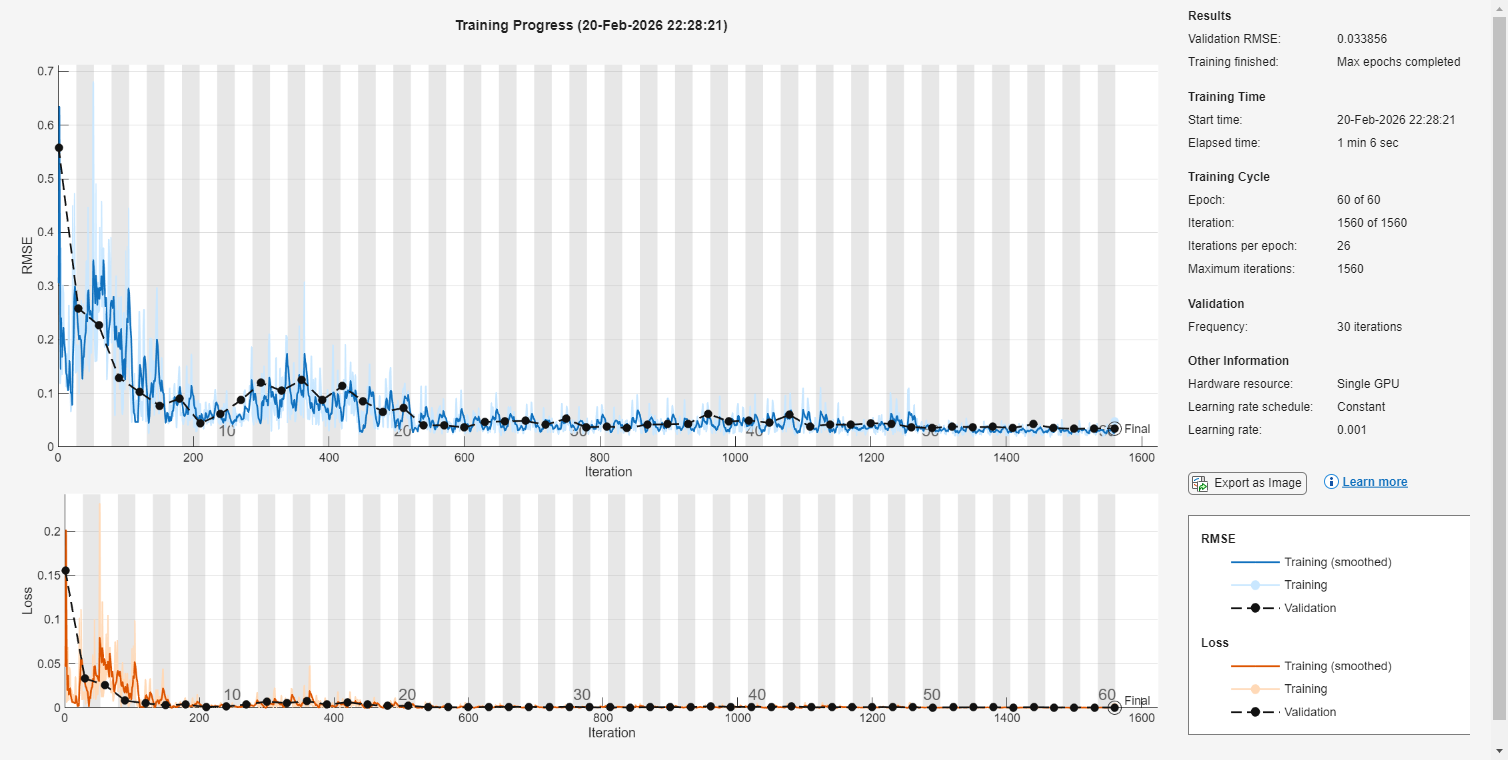


%% =========================
% 8) TRAINING (Adam)
% =========================

% validation split from the end of train (keep time-order)
valFrac = 0.15;
valN = max(1, floor(valFrac * numel(XtrainZ)));

Xval = XtrainZ(end-valN+1:end);
Yval = Ytrain(end-valN+1:end);

Xtr  = XtrainZ(1:end-valN);
Ytr  = Ytrain(1:end-valN);

options = trainingOptions("adam", ...
    "MaxEpochs", 60, ...
    "MiniBatchSize", 32, ...
    "InitialLearnRate", 1e-3, ...
    "GradientThreshold", 1, ...
    "Shuffle","never", ...   % IMPORTANT: time series
    "ValidationData",{Xval,Yval}, ...
    "ValidationFrequency", 30, ...
    "Verbose", true, ...
    "Plots","training-progress");

net = trainNetwork(Xtr, Ytr, lgraph, options);

%% =========================
% 9) PREDICT + EVALUATE
% =========================
Ypred = predict(net, XtestZ);

mseVal  = mean((Ypred - Ytest).^2);
rmseVal = sqrt(mseVal);
maeVal  = mean(abs(Ypred - Ytest));

SSres = sum((Ytest - Ypred).^2);
SStot = sum((Ytest - mean(Ytest)).^2) + eps;
r2Val = 1 - SSres/SStot;

fprintf("\nTransformer Test Metrics:\n");


Transformer Test Metrics:


fprintf("MSE  = %.6f\n", mseVal);

MSE  = 0.001048


fprintf("RMSE = %.6f\n", rmseVal);

RMSE = 0.032380


fprintf("MAE  = %.6f\n", maeVal);

MAE  = 0.026957


fprintf("R^2  = %.6f\n", r2Val);

R^2  = 0.162654


%% =========================
% 10) SIGNAL GENERATION (Hybrid)
% =========================

% Align test arrays with predictions
idxTest0 = split+1;             % first test sample index in aligned arrays

priceT = price_aligned(idxTest0:end);
upperT = upper_aligned(idxTest0:end);
lowerT = lower_aligned(idxTest0:end);
pctBT  = pctB_aligned(idxTest0:end);
datesT = dates_aligned(idxTest0:end);

% Hybrid rules:
% - Mean reversion zones from Bollinger: %B low => oversold, %B high => overbought
% - Transformer prediction must support direction
signals = zeros(size(Ypred));

boll_buy  = (pctBT <= 0.05) & (Ypred > 0);
boll_sell = (pctBT >= 0.95) & (Ypred < 0);

signals(boll_buy)  =  1;
signals(boll_sell) = -1;

% (Optional) if you want thresholding too:
% signals(Ypred > buy_threshold)  =  1;
% signals(Ypred < sell_threshold) = -1;

%% =========================
% 11) BACKTESTING ENGINE
% =========================
cash = initial_capital;
shares = 0;

portfolio_value = zeros(numel(priceT),1);

for t = 1:numel(priceT)
    px  = priceT(t);
    sig = signals(t);

    % Buy: only if flat
    if sig == 1 && shares == 0
        trade_value = cash * position_frac;
        qty = floor(trade_value / (px * (1 + commission)));
        cost = qty * px * (1 + commission);

        if qty > 0 && cost <= cash
            cash   = cash - cost;
            shares = qty;
        end

    % Sell: only if holding
    elseif sig == -1 && shares > 0
        proceeds = shares * px * (1 - commission);
        cash   = cash + proceeds;
        shares = 0;
    end

    portfolio_value(t) = cash + shares * px;
end

% Buy & hold benchmark from first test day
bench_shares = floor(initial_capital / priceT(1));
bench_cash   = initial_capital - bench_shares * priceT(1);
bench_value  = bench_cash + bench_shares * priceT;

% Returns
strategy_ret = [0; diff(portfolio_value)./portfolio_value(1:end-1)];
bench_ret    = [0; diff(bench_value)./bench_value(1:end-1)];

strategy_cum = cumprod(1 + strategy_ret) - 1;
bench_cum    = cumprod(1 + bench_ret) - 1;

%% =========================
% 12) PERFORMANCE METRICS
% =========================
tradingDays = 252;
Tdays = numel(strategy_ret);
years = Tdays / tradingDays;

finalStrat = portfolio_value(end) / portfolio_value(1);
finalBench = bench_value(end) / bench_value(1);

annRetStrat = finalStrat^(1/years) - 1;
annRetBench = finalBench^(1/years) - 1;

% Sharpe (rf ignored; subtract rfDaily if you want)
sharpeStrat = sqrt(tradingDays) * mean(strategy_ret) / (std(strategy_ret) + eps);
sharpeBench = sqrt(tradingDays) * mean(bench_ret) / (std(bench_ret) + eps);

% Max drawdown
peak = cummax(portfolio_value);
dd = (portfolio_value - peak) ./ peak;
maxDD = min(dd);

fprintf("\nBacktest (TEST period):\n");


Backtest (TEST period):


fprintf("Annualized Return: %.2f%% (strategy) vs %.2f%% (bench)\n", 100*annRetStrat, 100*annRetBench);

Annualized Return: 6.91% (strategy) vs 23.18% (bench)


fprintf("Sharpe Ratio:      %.2f (strategy) vs %.2f (bench)\n", sharpeStrat, sharpeBench);

Sharpe Ratio:      1.78 (strategy) vs 0.96 (bench)


fprintf("Max Drawdown:      %.2f%%\n", 100*maxDD);

Max Drawdown:      -3.35%


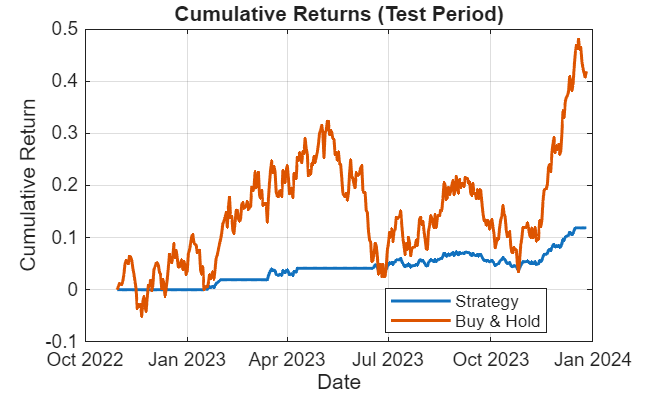

%% =========================
% 13) PLOTS
% =========================
figure;
plot(datesT, strategy_cum, 'LineWidth', 1.5); hold on;
plot(datesT, bench_cum, 'LineWidth', 1.5);
grid on;
legend("Strategy","Buy & Hold","Location","best");
title("Cumulative Returns (Test Period)");
xlabel("Date"); ylabel("Cumulative Return");

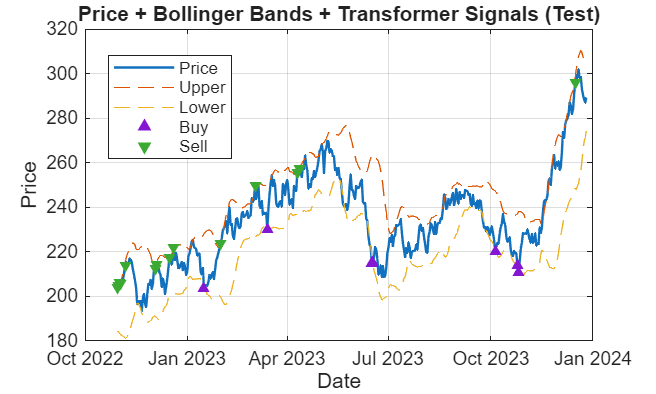


figure;
plot(datesT, priceT, 'LineWidth', 1.2); hold on;
plot(datesT, upperT, '--');
plot(datesT, lowerT, '--');

buyIdx  = (signals == 1);
sellIdx = (signals == -1);

scatter(datesT(buyIdx),  priceT(buyIdx),  28, '^', 'filled');
scatter(datesT(sellIdx), priceT(sellIdx), 28, 'v', 'filled');

grid on;
title("Price + Bollinger Bands + Transformer Signals (Test)");
legend("Price","Upper","Lower","Buy","Sell","Location","best");
xlabel("Date"); ylabel("Price");

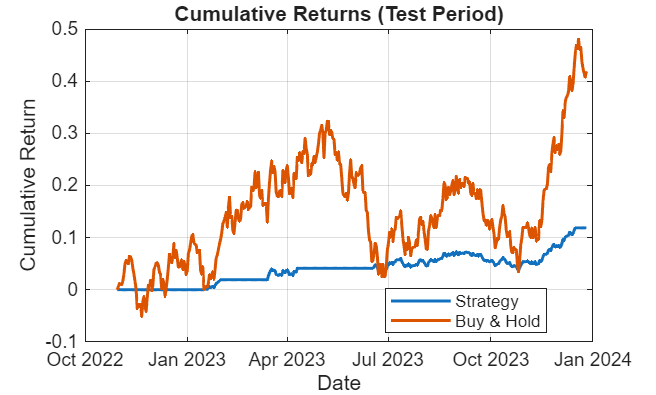

%% =========================
% SAVE RESULTS TO FOLDER
% =========================

% Create results folder if it doesn't exist
resultsFolder = "results";

if ~exist(resultsFolder, 'dir')
    mkdir(resultsFolder);
end

%% --- Save Equity Curve ---

figure;
plot(datesT, strategy_cum, 'LineWidth', 1.5); hold on;
plot(datesT, bench_cum, 'LineWidth', 1.5);
grid on;
legend("Strategy","Buy & Hold","Location","best");
title("Cumulative Returns (Test Period)");
xlabel("Date"); ylabel("Cumulative Return");

saveas(gcf, fullfile(resultsFolder, "equity_curve.png"));

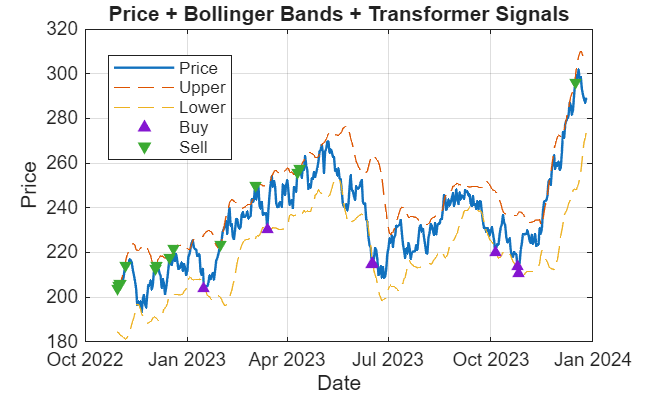


%% --- Save Signals Plot ---

figure;
plot(datesT, priceT, 'LineWidth', 1.2); hold on;
plot(datesT, upperT, '--');
plot(datesT, lowerT, '--');

buyIdx  = (signals == 1);
sellIdx = (signals == -1);

scatter(datesT(buyIdx),  priceT(buyIdx),  30, '^', 'filled');
scatter(datesT(sellIdx), priceT(sellIdx), 30, 'v', 'filled');

grid on;
title("Price + Bollinger Bands + Transformer Signals");
legend("Price","Upper","Lower","Buy","Sell","Location","best");
xlabel("Date"); ylabel("Price");

saveas(gcf, fullfile(resultsFolder, "signals_plot.png"));


%% --- Save Training Plot (if exists) ---

%% --- Save Training Plot (SAFE VERSION) ---

figHandles = findall(0,'Type','figure');

for i = 1:length(figHandles)
    figName = get(figHandles(i),'Name');

    % Check if figName is text before using contains
    if ischar(figName) || isstring(figName)
        if ~isempty(figName)
            if contains(lower(string(figName)), "training")
                saveas(figHandles(i), fullfile(resultsFolder, "training_curve.png"));
            end
        end
    end
end